[Response_GMM_1541,Response_MSM_1541] = D4_function(1541,[false,false],subject_list,data,icadata);
[Response_GMM_1536,Response_MSM_1536] = D4_function(1536,[false,false],subject_list,data,icadata);

figure(1)
fm=512;
t_response=-2.5+1/fm:1/fm:2.5;
plot(t_response,Response_GMM_1541(30,:))
hold on 
plot(t_response,Response_GMM_1536(30,:))
hold off
xlabel('seconds');ylabel('μV');title('NO ica NO auto');legend('1541','1536')

[Response_GMM_1541_withica,Response_MSM_1541_withica] = D4_function(1541,[true,false],subject_list,data,icadata);
[Response_GMM_1536_withica,Response_MSM_1536_withica] = D4_function(1536,[true,false],subject_list,data,icadata);

figure(2)
plot(t_response,Response_GMM_1541_withica(30,:))
hold on 
plot(t_response,Response_GMM_1536_withica(30,:))
hold off
xlabel('seconds');ylabel('μV');title('YES ica NO auto');legend('1541','1536')

[Response_GMM_1541_withauto,Response_MSM_1541_withauto] = D4_function(1541,[false,true],subject_list,data,icadata);
[Response_GMM_1536_withauto,Response_MSM_1536_withauto] = D4_function(1536,[false,true],subject_list,data,icadata);

figure(3)
plot(t_response,Response_GMM_1541_withauto(30,:))
hold on 
plot(t_response,Response_GMM_1536_withauto(30,:))
hold off
xlabel('seconds');ylabel('μV');title('NO ica YES auto');legend('1541','1536')

[Response_GMM_1541_withica_withauto,Response_MSM_1541_withica_withauto] = D4_function(1541,[true,true],subject_list,data,icadata);
[Response_GMM_1536_withica_withauto,Response_MSM_1536_withica_withauto] = D4_function(1536,[true,true],subject_list,data,icadata);

figure(4)
plot(t_response,Response_GMM_1541_withica_withauto(30,:))
hold on 
plot(t_response,Response_GMM_1536_withica_withauto(30,:))
hold off
xlabel('seconds');ylabel('μV');title('YES ica YES auto');legend('1541','1536')

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Alex\eeg_options.m
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


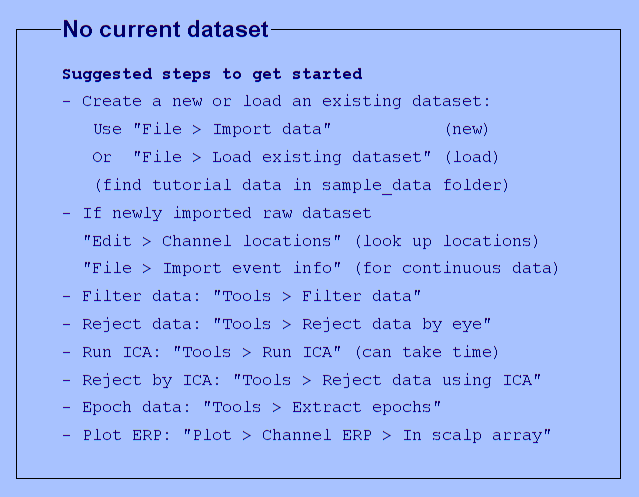


eeglab;close;


waitfor(msgbox("Now, please select your loc file without EOG channels", 'Loc file selection'));
[locs_noica,locpath_noica]=uigetfile('*.loc', 'Pick a channel location file');
locpath_noica=strrep(locpath_noica,'\','\\'); %for windows
locs_noica=append(locpath_noica,locs_noica);

H1=figure(10);
subplot(1,2,1)
D5_topoplots(Response_GMM_1541,locs_noica);title('1541 NO ica NO auto');

    2.1270    2.3262

readlocs(): 'loc' format assumed from file extension


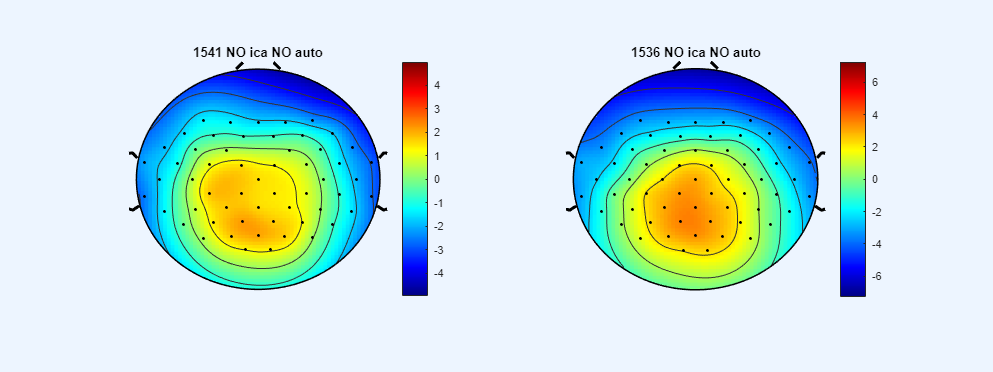

    2.1855    2.3848

readlocs(): 'loc' format assumed from file extension


subplot(1,2,2)
D5_topoplots(Response_GMM_1536,locs_noica);title('1536 NO ica NO auto');

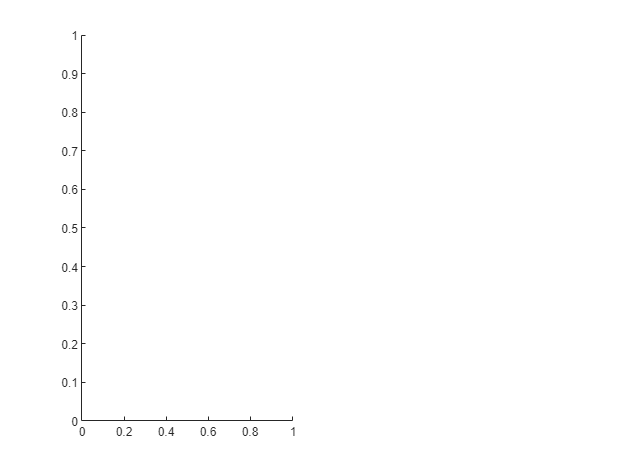

set(H1,'Position',[10 10 2000 750]);

H2=figure(11);
subplot(1,2,1)

D5_topoplots(Response_GMM_1541_withica,locs_noica);title('1541 YES ica NO auto');

Unrecognized function or variable 'Response_GMM_1541_withica'.

subplot(1,2,2)
D5_topoplots(Response_GMM_1536_withica,locs_noica);title('1536 YES ica NO auto');
set(H2,'Position',[10 10 2000 750]);

H3=figure(12);
subplot(1,2,1)
D5_topoplots(Response_GMM_1541_withauto,locs_noica);title('1541 NO ica YES auto');
subplot(1,2,2)
D5_topoplots(Response_GMM_1536_withauto,locs_noica);title('1536 NO ica YES auto');
set(H3,'Position',[10 10 2000 750]);

H4=figure(13);
subplot(1,2,1)
D5_topoplots(Response_GMM_1541_withica_withauto,locs_noica);title('1541 YES ica YES auto');
subplot(1,2,2)
D5_topoplots(Response_GMM_1536_withica_withauto,locs_noica);title('1536 YES ica YES auto');
set(H4,'Position',[10 10 2000 750]);